依赖[统一实验分析作图v18.0.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

光声

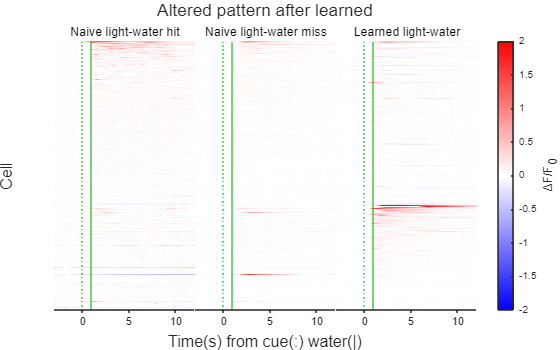

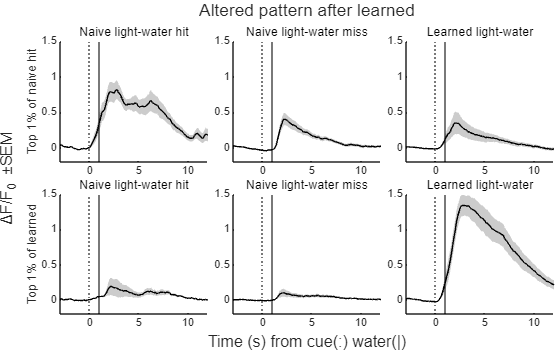

Impl(bitor(TransferLearning.Flags.PPT,TransferLearning.Flags.LightAudio));

声光

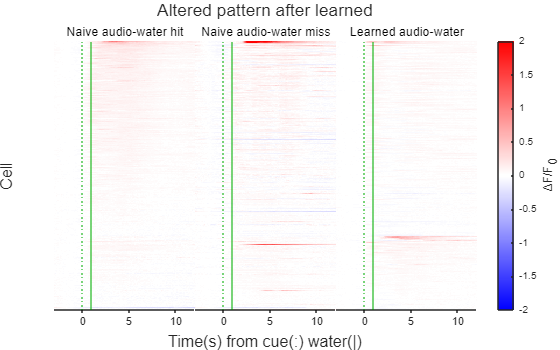

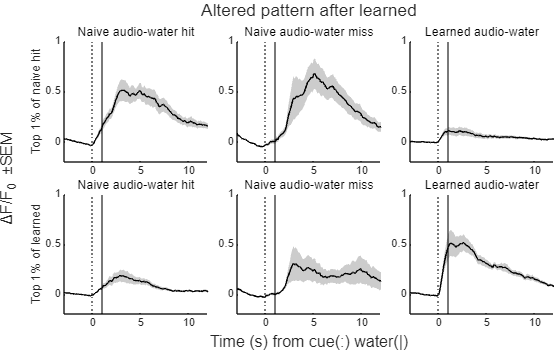

Impl(bitor(TransferLearning.Flags.PPT,TransferLearning.Flags.AudioLight));

function Impl(FigureFlag)
import TransferLearning.*
DataSet=FullCalcium;
switch bitand(FigureFlag,Flags.Paradigm)
	case Flags.LightAudio
		SheetName='光声Naive命中错失';
		Stimulus='light-water';
	case Flags.AudioLight
		SheetName='声光Naive命中错失';
		Stimulus='audio-water';
	otherwise
		Exception.Unsupported_paradigm.Throw;
end
Calcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(ProjectPath('查询表.xlsx'),SheetName),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));
Calcium=Calcium(any(Calcium.NTATS.Naive_hit,2),:);
SubTitles=compose(["Naive %s hit","Naive %s miss","Learned %s"],Stimulus);
Layout=BasicHeatmap(UniExp.HeatmapSort(Calcium,["Naive_hit","Learned"]).NTATS{:,:,["Naive_hit","Naive_miss","Learned"]},SubTitles,GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]),false,CLim=[-2,2]);
Target=Flags(bitand(FigureFlag,Flags.Target));
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp2/5, %u cells, %u mice',height(Calcium),numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,Calcium.CellUID))))));
		MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
	case Flags.PPT
		title(Layout,'Altered pattern after learned');
		MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
	otherwise
		Exception.Unsupported_target.throw;
end
print(ProjectPath(sprintf('%s.热图.%s.svg',SheetName,Target)),'-dsvg');

取 Naive hit 和Learned前1%强细胞

Index5P=1:uint8(height(Calcium)/100);
[~,SortIndex]=sort(sum(Calcium.NTATS.Naive_hit,2),'descend');
[NaiveMean,NaiveSem]=MATLAB.DataFun.MeanSem(Calcium(SortIndex(Index5P),:).NTATS{:,:,["Naive_hit","Naive_miss","Learned"]},1);
[~,SortIndex]=sort(sum(Calcium.NTATS.Learned,2),'descend');
[LearnedMean,LearnedSem]=MATLAB.DataFun.MeanSem(Calcium(SortIndex(Index5P),:).NTATS{:,:,["Naive_hit","Naive_miss","Learned"]},1);
Xs=linspace(-3,12,size(NaiveMean,2))';

作三种条件下的曲线

figure;
Layout=tiledlayout(2,3,TileSpacing='tight',Padding='tight');
Axes=gobjects(2,3);
for A=1:3
	Axes(1,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(NaiveMean(:,:,A)',NaiveSem(:,:,A)',X=Xs);
	xline(0,':k');
	xline(1,'-k');
	title(SubTitles(A));
end
for A=1:3
	Axes(2,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(LearnedMean(:,:,A)',LearnedSem(:,:,A)',X=Xs);
	xline(0,':k');
	xline(1,'-k');
	title(SubTitles(A));
end
ylabel(Axes(1,1),'Top 1% of naive hit');
ylabel(Axes(2,1),'Top 1% of learned');
xlabel(Layout,'Time (s) from cue(:) water(|)');
ylabel(Layout,'ΔF/F_0 ±SEM');
MATLAB.UnifyYLims(Axes);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp2/5 %u cells',numel(Index5P)));
	case Flags.PPT
		title(Layout,'Altered pattern after learned');
	otherwise
		Exception.Unsupported_target.throw;
end
print(ProjectPath(sprintf('%s.线图.%s.svg',SheetName,Target)),'-dsvg');
end